# Basketball Players

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and formats the data.

data = readtable("./data/bball.csv");
data.pos = categorical(data.pos);

This code extracts and normalizes the columns of interest.

stats = data{:, [5 6 11:end]};
statsNorm = normalize(stats);

## Task 1

grp = kmeans(statsNorm, 2, "Replicates", 5);

This code performs PCA and plots the transformed data by group.

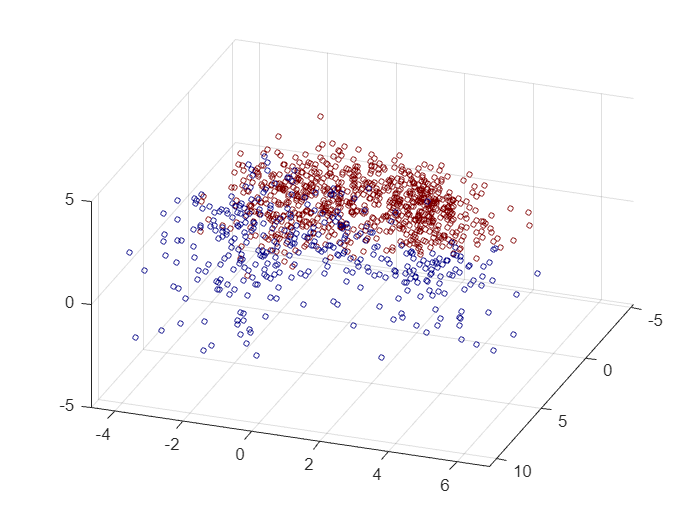

[pcs, scrs] = pca(statsNorm);
scatter3(scrs(:, 1), scrs(:, 2), scrs(:, 3), 10, grp)
colormap(jet)
view(110, 40)